# Lab Activity 8

#### ### Insert Name ###

## Prepare Workspace

close all
clear

load lab8dat.mat

## Item 2

% Complete the following line and Uncomment to Run
b = [ 1 1 1 1 1 ]/5;  % <--- complete this line

% Use the filter command to compute the convolution
y = filter(b,1,x1);

% Complete the following lines and Uncomment to Run
nstart = 0; % <--- complete this line
nstop = length(x1)-1; % <--- complete this line
n = nstart:nstop;

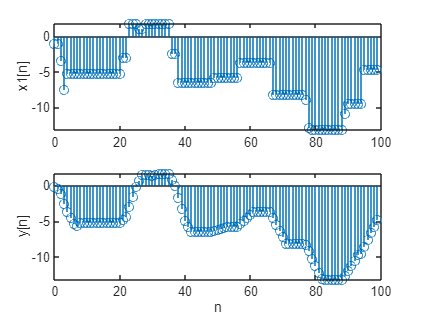

% Plotting 
figure
subplot(211)
stem(n, x1(n+1))  % offset by 1 since MATLAB starts indexing at 1, not 0
ylabel('x1[n]')
subplot(212)
stem(n,y(n+1))
ylabel('y[n]')
xlabel('n')

## Item 3

x = 256*(rem(0:100,50)<10);

% Complete the following line and Uncomment to Run
b = [1,-.9]  % <--- complete this line

b =     1.0000   -0.9000


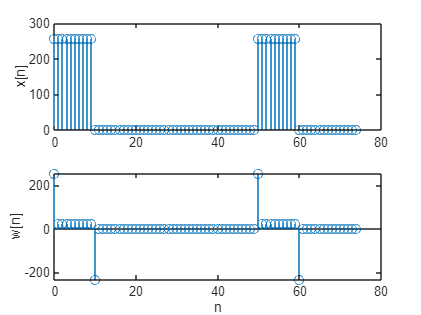

w = filter(b,1,x);
 
nstart = 0; 
nstop = 74; 
n = nstart:nstop;

figure
subplot(211)
stem(n, x(n+1))  % offset by 1 since MATLAB starts indexing at 1, not 0
ylabel('x[n]')
subplot(212)
stem(n,w(n+1))
ylabel('w[n]')
xlabel('n')

## Item 4

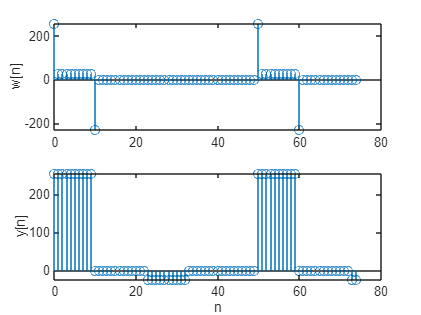

% Complete the following line and Uncomment to Run
r = .9;  % <--- complete this line
M = 22;  % <--- complete this line

b_deconv = r.^[0:M];

% Complete the following line and Uncomment to Run
y = filter(b_deconv,1,w);  % <--- complete this line
 
nstart = 0; 
nstop = 74; 
n = nstart:nstop;

figure
subplot(211)
stem(n, w(n+1))  % offset by 1 since MATLAB starts indexing at 1, not 0
ylabel('w[n]')
subplot(212)
stem(n,y(n+1))
ylabel('y[n]')
xlabel('n')

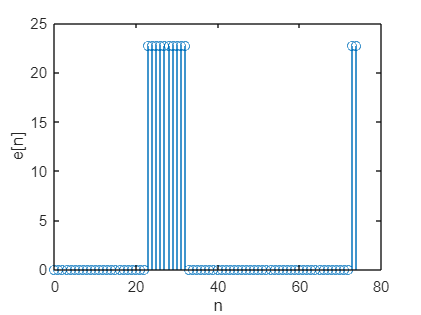


% Plotting the residual error.
e = x-y;

figure
stem(n,e(n+1))
ylabel('e[n]')
xlabel('n')


maxerr = max(abs(e))

maxerr = 22.6891